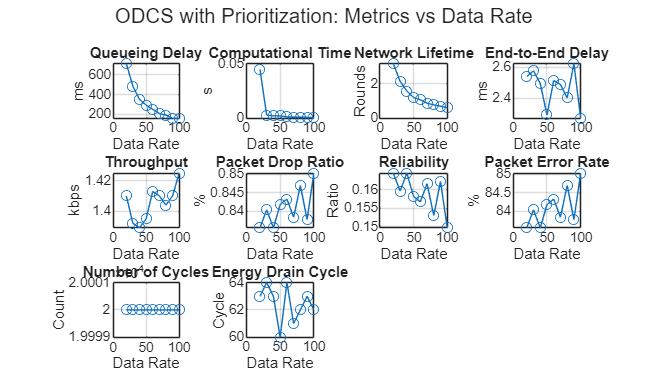

% ODCS with Traffic Prioritization and Binary Data Classification (from OLQS)
clc; clear;

%% Parameters
areaSize = 250;                 
numRelays = 7;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;  
range = 50;                     
initialEnergy = 7;             
energyThreshold = 0.2 * initialEnergy;
normalTemp = 37;               
tempThreshold = 39;            
criticalThreshold = 40;        
frequency = 2.4e9;             
packetSize = 3000 / 8;         
dataRates = 20:10:100;         
simTime = 1000;                
queueDelayBase = 5; queueVar = 10;

% Energy model
txDirect = 0.1;
txRelay = 0.05;
rxRelay = 0.05;
activeIdle = 0.001;
sleepMode = 0.0001;

%% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;
statuses = repmat("Sleep", numNodes, 1);

%% Load Sensor Data
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) < 5
    error('Expected at least 5 columns: HR, BP, BT, RR, BS');
end

numCycles = size(sensorData, 1); % For Number of Cycles

%% Metrics Initialization
energyPerSource = zeros(length(dataRates), numSources);
metrics = zeros(length(dataRates), 10); 
% Columns: QueueDelay, Time, Lifetime, E2EDelay, Throughput, DropRatio, Reliability, PER, Cycles, EnergyDrainCycle

%% Start Simulation
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);
    statuses(:) = "Sleep";
    energyDrainCycle = 0;

    totalQueueDelay = 0;
    totalE2EDelay = zeros(numCycles, 1);
    networkLifetime = 0;
    tStart = tic;

    totalPacketsSent = 0;
    totalPacketsReceived = 0;
    totalPacketsDropped = 0;

    for t = 1:numCycles
        roundE2EDelay = 0; validCount = 0;
        statuses(:) = "Sleep";

        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end

            % Read physiological values for prioritization
            HR = sensorData(t,1); BP = sensorData(t,2); BT = sensorData(t,3);
            RR = sensorData(t,4); BS = sensorData(t,5);

            % Determine if current data is critical
            isCritical = false;
            switch s
                case 1, isCritical = (HR < 50 || HR > 120);
                case 2, isCritical = (BP >= 180 || BP <= 90);
                case 3, isCritical = (BT >= 40 || BT < 35);
                case 4, isCritical = (RR < 8 || RR > 30);
                case 5, isCritical = (BS < 54 || BS >= 300);
            end

            % Binary assignment
            if isCritical
                binaryData = [0 1];
            else
                binaryData = [0 0];
            end

            totalPacketsSent = totalPacketsSent + 1;
            statuses(srcID) = "Active";

            if isCritical
                distToSink = norm(positions(srcID,:) - positions(sinkID,:));
                delay = rand() * 100 + distToSink * 0.1;
                roundE2EDelay = roundE2EDelay + delay;

                energy(srcID) = energy(srcID) - txDirect;

                if energy(srcID) < energyThreshold
                    nodeDead(srcID) = true;
                    totalPacketsDropped = totalPacketsDropped + 1;
                else
                    totalPacketsReceived = totalPacketsReceived + 1;
                end
            else
                dists = vecnorm(positions - positions(srcID,:), 2, 2);
                eligibleRelays = find(dists <= range & roles == "Relay" & ~nodeDead);

                if isempty(eligibleRelays)
                    totalPacketsDropped = totalPacketsDropped + 1;
                    continue;
                end

                relayID = eligibleRelays(randi(length(eligibleRelays)));

                if srcID <= numNodes && relayID <= numNodes
                    statuses([srcID, relayID]) = "Active";

                    delay = rand() * queueVar + queueDelayBase;
                    roundE2EDelay = roundE2EDelay + delay;

                    energy(srcID) = energy(srcID) - txRelay;
                    energy(relayID) = energy(relayID) - rxRelay;

                    if energy(srcID) < energyThreshold, nodeDead(srcID) = true; end
                    if energy(relayID) < energyThreshold, nodeDead(relayID) = true; end

                    if nodeDead(srcID) || nodeDead(relayID)
                        totalPacketsDropped = totalPacketsDropped + 1;
                    else
                        totalPacketsReceived = totalPacketsReceived + 1;
                    end
                else
                    totalPacketsDropped = totalPacketsDropped + 1;
                end
            end

            % Energy Drain Cycle tracking
            if energyDrainCycle == 0 && any(energy(numRelays+1:numRelays+numSources) < energyThreshold)
                energyDrainCycle = t;
            end

            if networkLifetime == 0 && any(energy < energyThreshold)
                networkLifetime = t;
            end

            totalQueueDelay = totalQueueDelay + queueDelayBase;
            validCount = validCount + 1;
        end

        % Idle/Sleep energy consumption
        for n = 1:numNodes
            if ~nodeDead(n)
                if statuses(n) == "Active"
                    energy(n) = energy(n) - activeIdle;
                else
                    energy(n) = energy(n) - sleepMode;
                end
                if energy(n) < energyThreshold
                    nodeDead(n) = true;
                end
            end
        end

        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end

    % Compute metrics
    tComp = toc(tStart) / dataRate;
    throughput = (totalPacketsReceived * packetSize * 8) / (simTime * 1000);
    dropRatio = totalPacketsDropped / totalPacketsSent;
    reliability = totalPacketsReceived / totalPacketsSent;
    PER = dropRatio * 100;

    metrics(drIdx,:) = [
        totalQueueDelay / dataRate, ...
        tComp, ...
        networkLifetime / dataRate, ...
        mean(totalE2EDelay(~isnan(totalE2EDelay))), ...
        throughput, ...
        dropRatio, ...
        reliability, ...
        PER, ...
        numCycles, ...
        energyDrainCycle
    ];

    for s = 1:numSources
        srcID = numRelays + s;
        energyPerSource(drIdx,s) = initialEnergy - energy(srcID);
    end
end

%% Save Metrics
writematrix([dataRates(:), metrics(:,1)], 'Queueing_Delay_ODCS.csv');
writematrix([dataRates(:), metrics(:,2)], 'Computational_Time_ODCS.csv');
writematrix([dataRates(:), metrics(:,3)], 'Network_Lifetime_ODCS.csv');
writematrix([dataRates(:), metrics(:,4)], 'End_to_End_Delay_ODCS.csv');
writematrix([dataRates(:), metrics(:,5)], 'Throughput_ODCS.csv');
writematrix([dataRates(:), metrics(:,6)], 'Packet_Drop_Ratio_ODCS.csv');
writematrix([dataRates(:), metrics(:,7)], 'Reliability_ODCS.csv');
writematrix([dataRates(:), metrics(:,8)], 'Packet_Error_Rate_ODCS.csv');
writematrix([dataRates(:), metrics(:,9)], 'Number_of_Cycles_ODCS.csv');
writematrix([dataRates(:), metrics(:,10)], 'Energy_Drain_Cycle_ODCS.csv');
writematrix(energyPerSource, 'Energy_Source_Node_ODCS.csv');

%% Plot Results
figure;
subplot(3,4,1); plot(dataRates, metrics(:,1), '-o'); title('Queueing Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,4,2); plot(dataRates, metrics(:,2), '-o'); title('Computational Time'); xlabel('Data Rate'); ylabel('s'); grid on;
subplot(3,4,3); plot(dataRates, metrics(:,3), '-o'); title('Network Lifetime'); xlabel('Data Rate'); ylabel('Rounds'); grid on;
subplot(3,4,4); plot(dataRates, metrics(:,4), '-o'); title('End-to-End Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,4,5); plot(dataRates, metrics(:,5), '-o'); title('Throughput'); xlabel('Data Rate'); ylabel('kbps'); grid on;
subplot(3,4,6); plot(dataRates, metrics(:,6), '-o'); title('Packet Drop Ratio'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,4,7); plot(dataRates, metrics(:,7), '-o'); title('Reliability'); xlabel('Data Rate'); ylabel('Ratio'); grid on;
subplot(3,4,8); plot(dataRates, metrics(:,8), '-o'); title('Packet Error Rate'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,4,9); plot(dataRates, metrics(:,9), '-o'); title('Number of Cycles'); xlabel('Data Rate'); ylabel('Count'); grid on;
subplot(3,4,10); plot(dataRates, metrics(:,10), '-o'); title('Energy Drain Cycle'); xlabel('Data Rate'); ylabel('Cycle'); grid on;
sgtitle('ODCS with Prioritization: Metrics vs Data Rate');

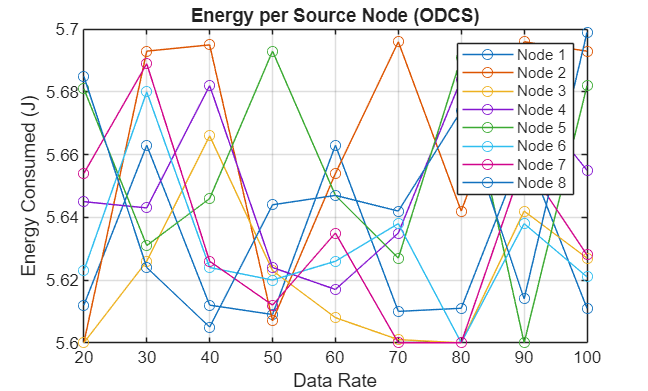


figure;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]); hold on;
end
xlabel('Data Rate'); ylabel('Energy Consumed (J)');
title('Energy per Source Node (ODCS)'); grid on; legend show;